# EE6133 : Multirate Digital Signal Processing

# Assignment 1

## Name : ANIRUDH B S (EE21B019)

## Magnitude Response of the Unprocessed Signals

Firstly, we will process the Speech signal sampled at 8kHz.

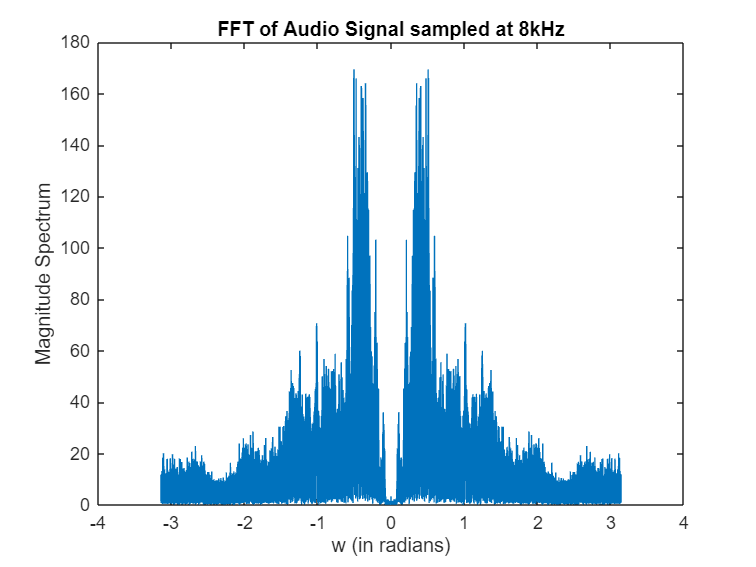

[y1,Fs1] = audioread("speech8khz.wav");
L1 = 80000;
Y1 = fft(y1);
Y1 = fftshift(Y1);
w1 = (-L1/2:L1/2-1) * (2*pi/L1);
plot(w1,abs(Y1)); 
title('FFT of Audio Signal sampled at 8kHz')
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

sound(y1,Fs1);

Now, we will process the Music Signal sampled at 16kHz.

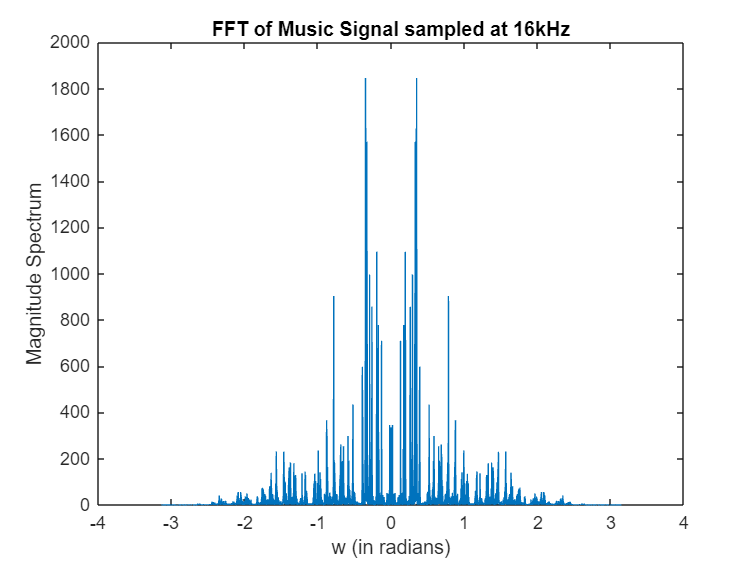

[y2,Fs2] = audioread("music16khz.wav");
L2 = 160000;
Y2 = fft(y2);
Y2 = fftshift(Y2);
w2 = (-L2/2:L2/2-1) * (2*pi/L2);
plot(w2,abs(Y2));
title('FFT of Music Signal sampled at 16kHz')
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

sound(y2,Fs2);

## **Downsample each audio signal by 2 without any AA filtering. Play back using the new sampling rate.**

In this section, we will downsample the signals by a factor of 2 without any Anti-Aliasing Filter upfront. 

To do this operation, we will use the downsample command in MATLAB.

Again, we start with the Speech Signal.

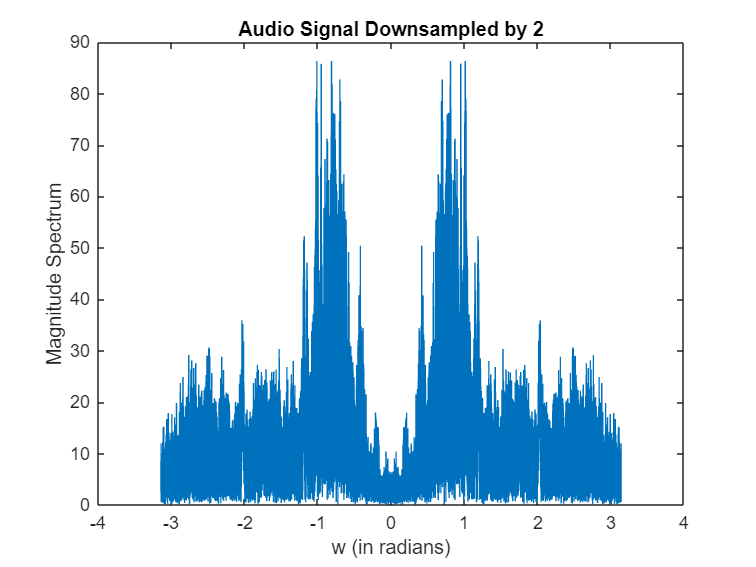

y1_down = downsample(y1,2);
Ld1 = 40000;
Yd1 = fft(y1_down);
Yd1 = fftshift(Yd1);
w1d = (-Ld1/2:Ld1/2-1) * (2*pi/Ld1);
plot(w1d,abs(Yd1));
title('Audio Signal Downsampled by 2')
xlabel('w (in radians)');
ylabel('Magnitude Spectrum')

sound(y1_down,Fs1/2);

#### Observation after downsampling

From the magnitude spectrum it appears that there has been significant aliasing. This results in the audio being slightly unclear. 

Now, we move on to the Music Signal.

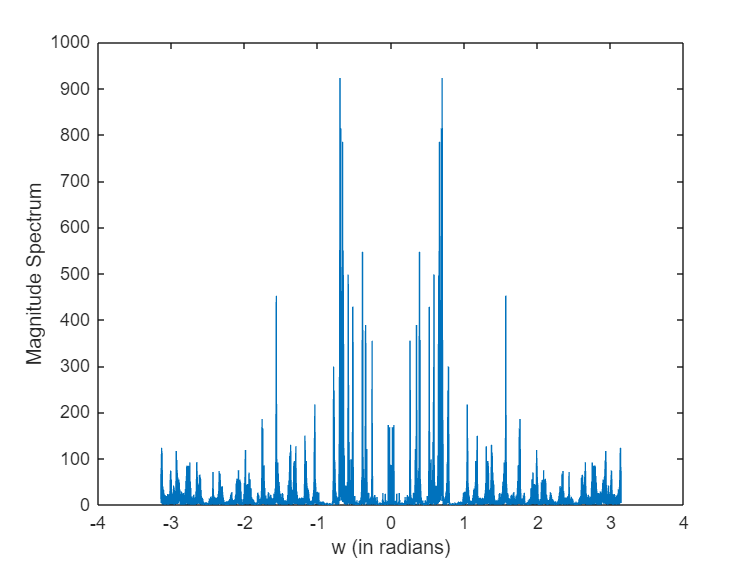

y2_down = downsample(y2,2);
Ld2 = 80000;
Yd2 = fft(y2_down);
Yd2 = fftshift(Yd2);
w2d = (-Ld2/2:Ld2/2-1) * (2*pi/Ld2);
plot(w2d,abs(Yd2));
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

sound(y2_down,Fs2/2);

### **Observation after downsampling**

There doesn't seem to be much difference in downsampled signal and the original one. But if we compare the fft plots, we can see there is some amount of aliasing happening.

## Design an equiripple LPF with ωp = 0.45π and ωs = 0.55π, with appropriate values for δp and δs. Using this as an AA filter, downsample each audio signal by 2. Play back using the new sampling rate. Compare the two downsampled signals (with and without AA filtering) for each audio input.

To design the equiripple filter, I have used the fdesign function. The pass-band ripple is set to 1 dB and attenuation in stop band is 60 dB. This has been used throughout the assignment. 

lp1 = fdesign.lowpass('Fp,Fst,Ap,Ast',1800,2200,1,60,Fs1);
lpf1 = design(lp1,'equiripple');
fvtool(lpf1)

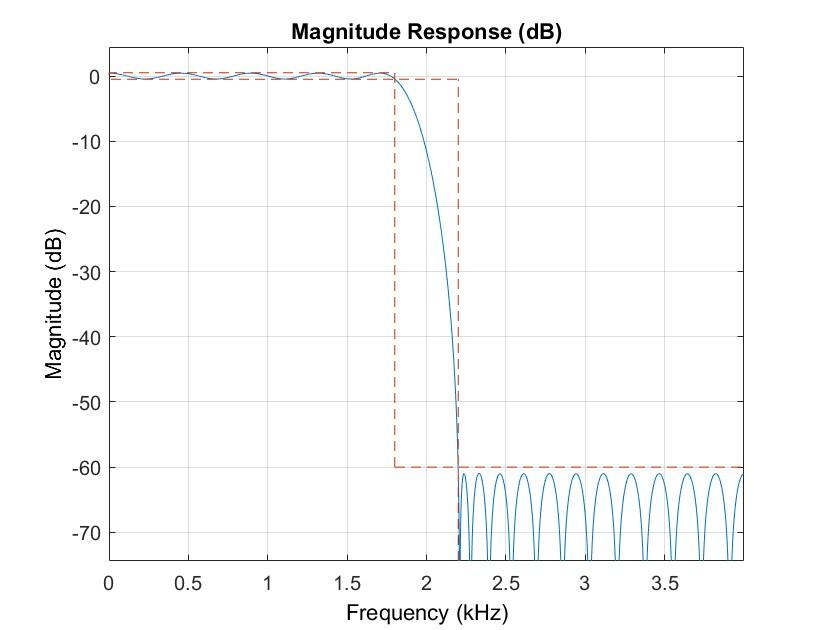

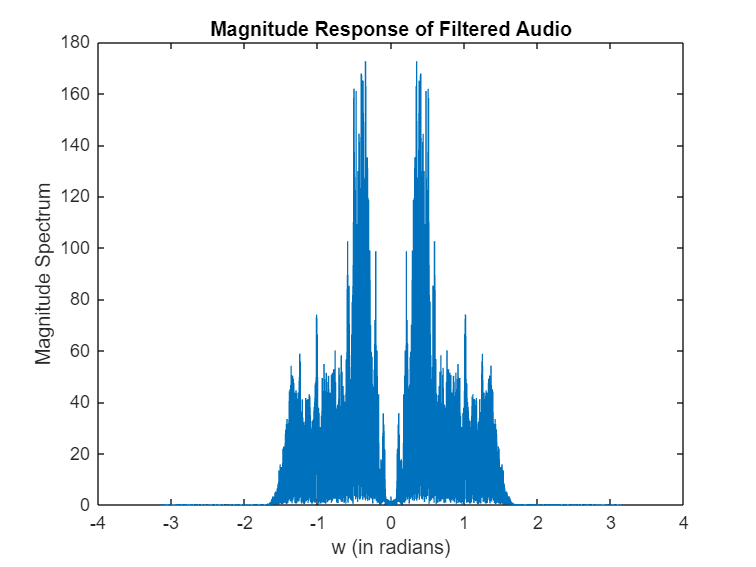

y_aa1 = filter(lpf1,y1);
Yaa1 = fft(y_aa1);
Yaa1 = fftshift(Yaa1);
plot(w1,abs(Yaa1));
title('Magnitude Response of Filtered Audio');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

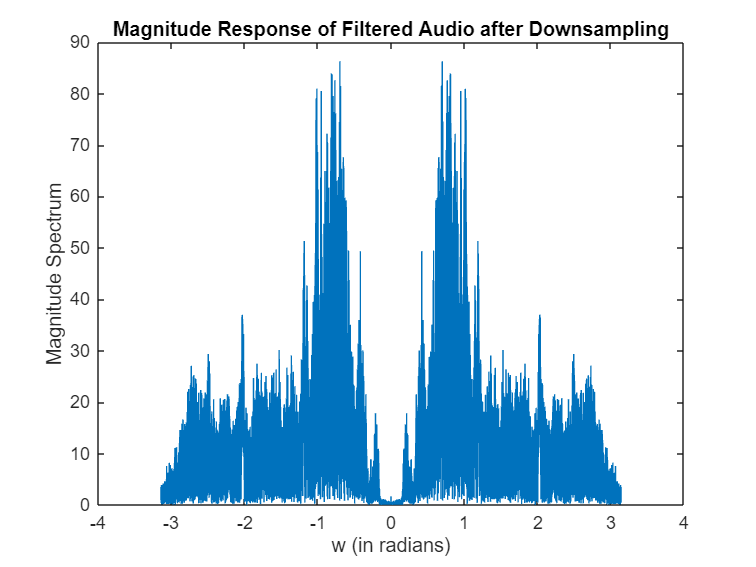

y_aa1_d = downsample(y_aa1,2);
Yaa1_d = fft(y_aa1_d);
Yaa1_d = fftshift(Yaa1_d);
plot(w1d,abs(Yaa1_d));
title('Magnitude Response of Filtered Audio after Downsampling');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

sound(y_aa1_d,Fs1/2);

### Observation 

After comparing the two speech files from problem 1 and problem 2, it is observed that the signal which is AA filtered before downsampling is more coherent than the unfiltered one.

Now, we move on to the Music Signal. 

lp2 = fdesign.lowpass('Fp,Fst,Ap,Ast',3600,4400,1,60,Fs2);
lpf2 = design(lp2,'equiripple');
fvtool(lpf2)

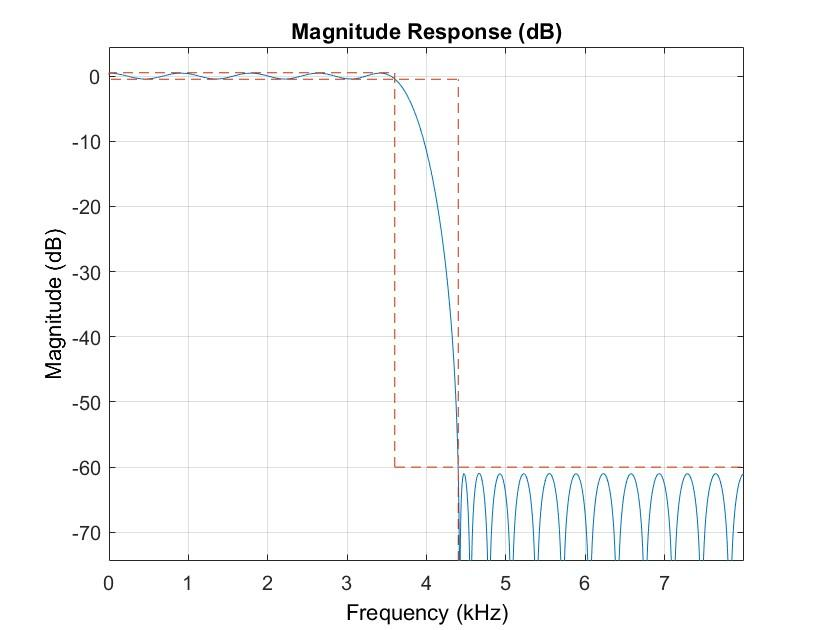

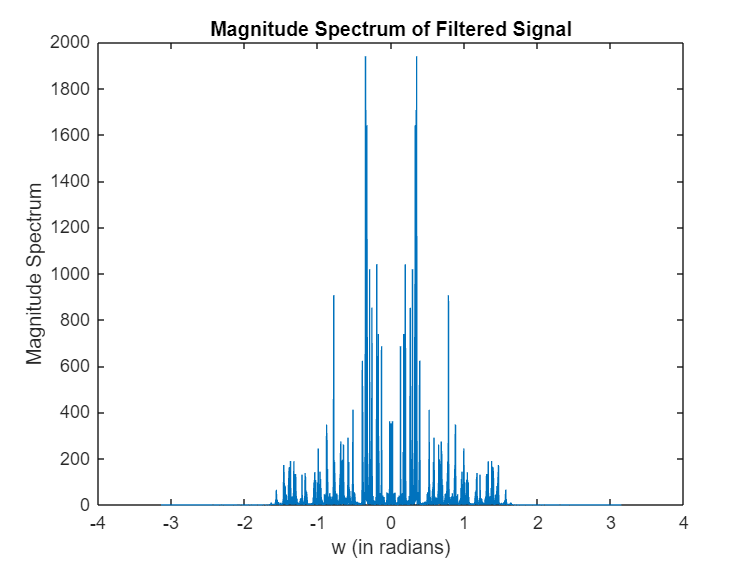

y_aa2 = filter(lpf2,y2);
Yaa2 = fft(y_aa2);
Yaa2 = fftshift(Yaa2);
plot(w2,abs(Yaa2));
title('Magnitude Spectrum of Filtered Signal');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

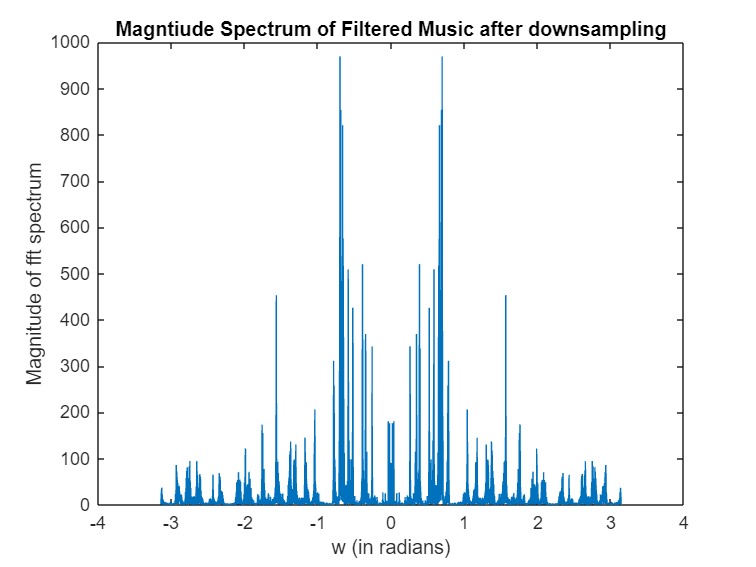

y_aa2_d = downsample(y_aa2,2);
Yaa2_d = fft(y_aa2_d);
Yaa2_d = fftshift(Yaa2_d);
plot(w2d,abs(Yaa2_d));
title('Magntiude Spectrum of Filtered Music after downsampling')
xlabel('w (in radians)');
ylabel('Magnitude of fft spectrum');

sound(y_aa2_d,Fs2/2);

### Observation

It feels as though the music played after downsampling is changing more gradually than the unprocessed music, which is very obvious. If we compare the fft magnitude plots, we can see that the signal passed through the AA filter has less aliasing. 

## Design an equiripple LPF with ωp = 0.22π and ωs = 0.28π

Designing the filter for speech file (8 KHz sampling frequency).

lp3 = fdesign.lowpass('Fp,Fst,Ap,Ast',880,1120,1,60,Fs1);
lpf3 = design(lp3,'equiripple');
fvtool(lpf3)

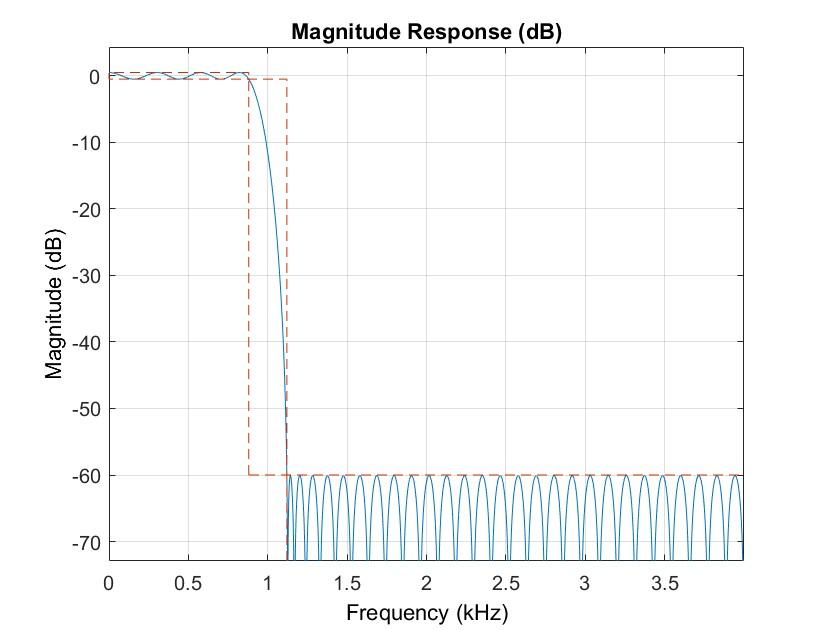

Designing the filter for music file (16 KHz sampling frequency).

lp4 = fdesign.lowpass('Fp,Fst,Ap,Ast',1760,2240,1,60,Fs2);
lpf4 = design(lp4,'equiripple');
fvtool(lpf4);

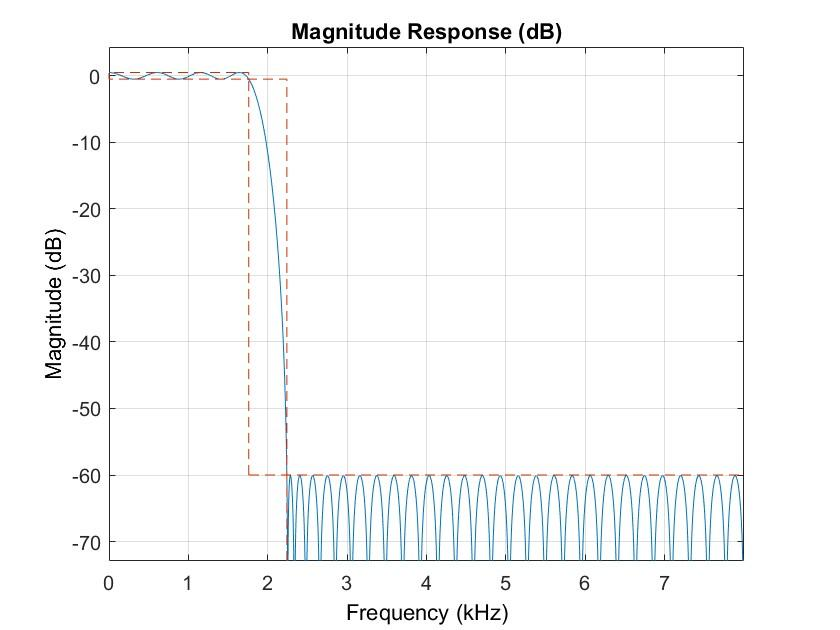

## First upsample each original audio signal by 3. Then apply the LPF with cutoff-π/4 designed above, and downsample by 4. Play the re-sampled outputs using the new sampling rate. Compare these outputs with the originals.

Upsampling the speech signal.

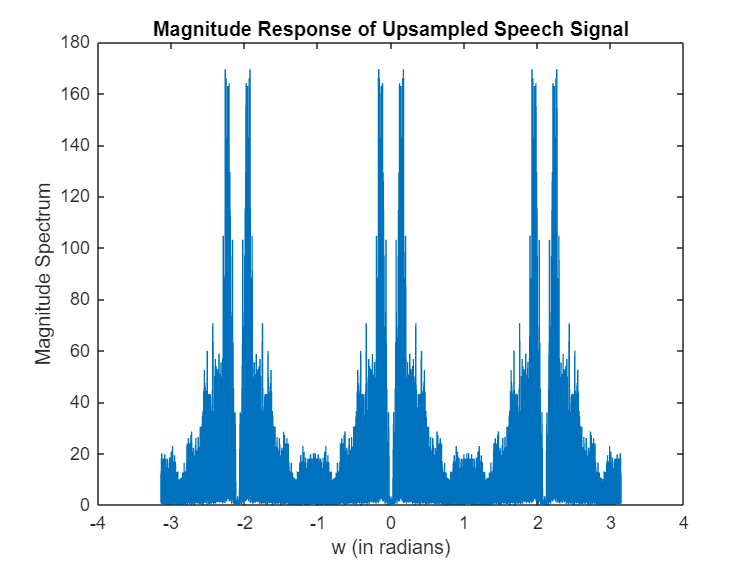

y_u1 = upsample(y1,3);
Lu1 = L1*3;
Yu1 = fft(y_u1);
Yu1 = fftshift(Yu1);
w1u = (-Lu1/2:Lu1/2-1) * (2*pi/Lu1);
plot(w1u,abs(Yu1));
title('Magnitude Response of Upsampled Speech Signal');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

Filtering the signal with LPF designed in part 3

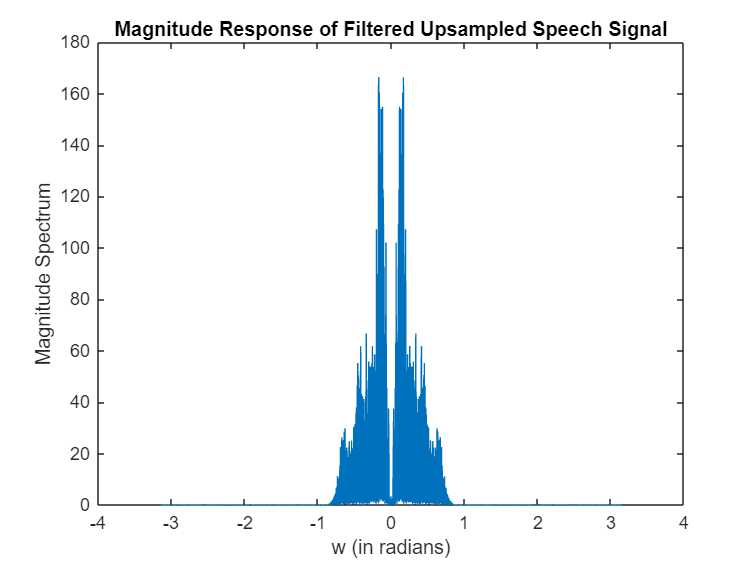

y_aa_u1 = filter(lpf3,y_u1);
Yaa_u1 = fft(y_aa_u1);
Yaa_u1 = fftshift(Yaa_u1);
plot(w1u,abs(Yaa_u1));
title('Magnitude Response of Filtered Upsampled Speech Signal');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

Now downsampling the signal by 4.

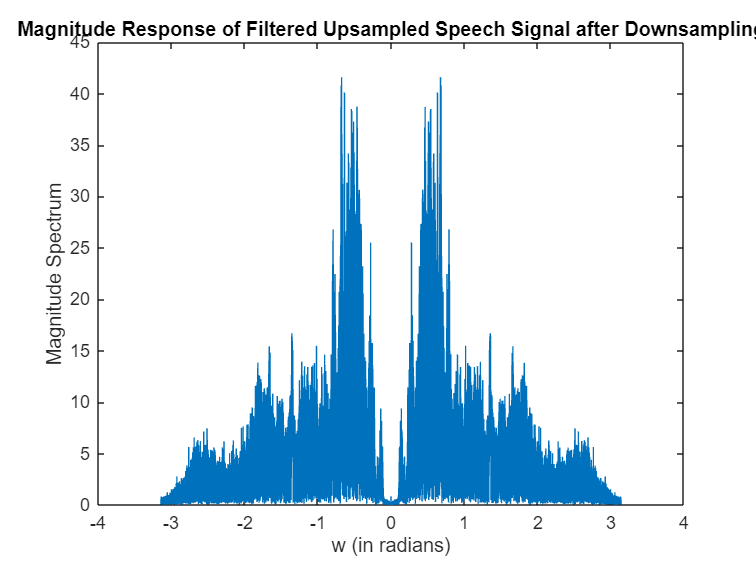

y_aa_ud1 = downsample(y_aa_u1,4);
Lud1 = Lu1/4;
Yaa_ud1 = fft(y_aa_ud1);
Yaa_ud1 = fftshift(Yaa_ud1);
w1ud = (-Lud1/2:Lud1/2-1) * (2*pi/Lud1);
plot(w1ud,abs(Yaa_ud1));
title('Magnitude Response of Filtered Upsampled Speech Signal after Downsampling');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

sound(y_aa_ud1,3*Fs1/4);

### **Observation**

If we compare the speech file after the operations with the original one, the two signals are quite similar. This is because we are upsampling first and then downsampling, there is not signficant loss of information, though there is some loss of information. 

Upsampling the music file.

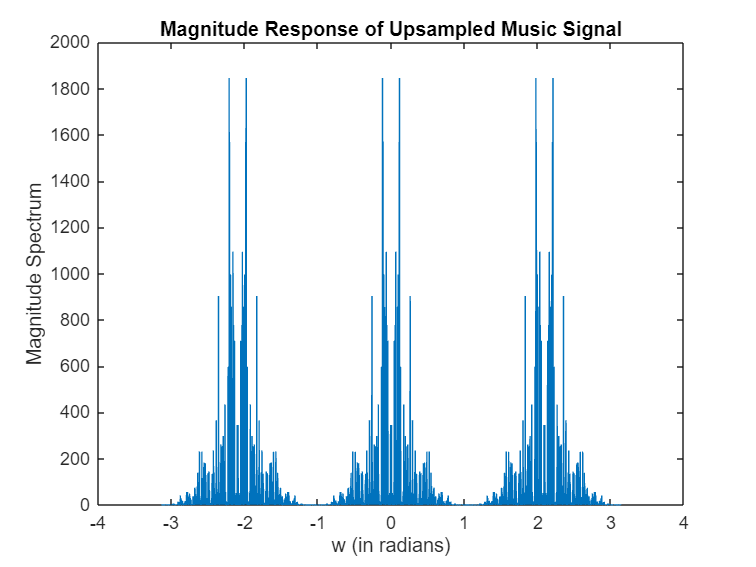

y_u2 = upsample(y2,3);
Lu2 = L2*3;
Yu2 = fft(y_u2);
Yu2 = fftshift(Yu2);
w2u = (-Lu2/2:Lu2/2-1) * (2*pi/Lu2);
plot(w2u,abs(Yu2));
title('Magnitude Response of Upsampled Music Signal');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

Filtering the signal with LPF designed in part 3.

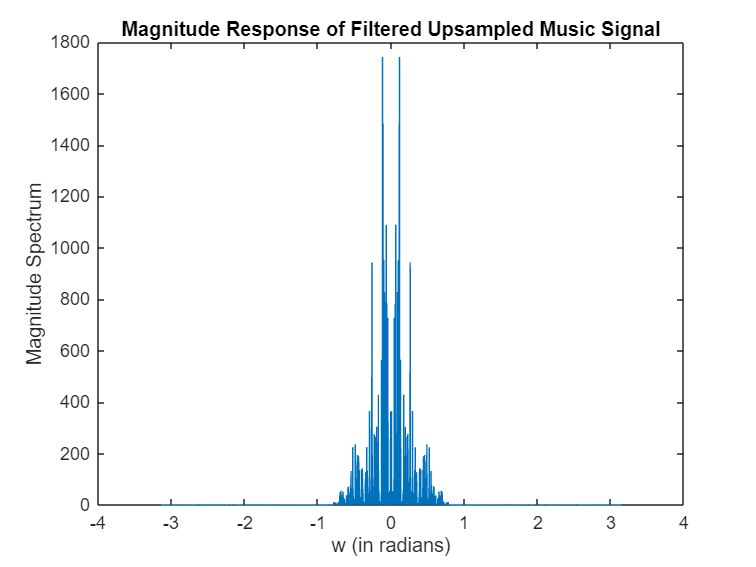

y_aa_u2 = filter(lpf4,y_u2);
Yaa_u2 = fft(y_aa_u2);
Yaa_u2 = fftshift(Yaa_u2);
plot(w2u,abs(Yaa_u2));
title('Magnitude Response of Filtered Upsampled Music Signal');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

Downsampling filtered signal by 4

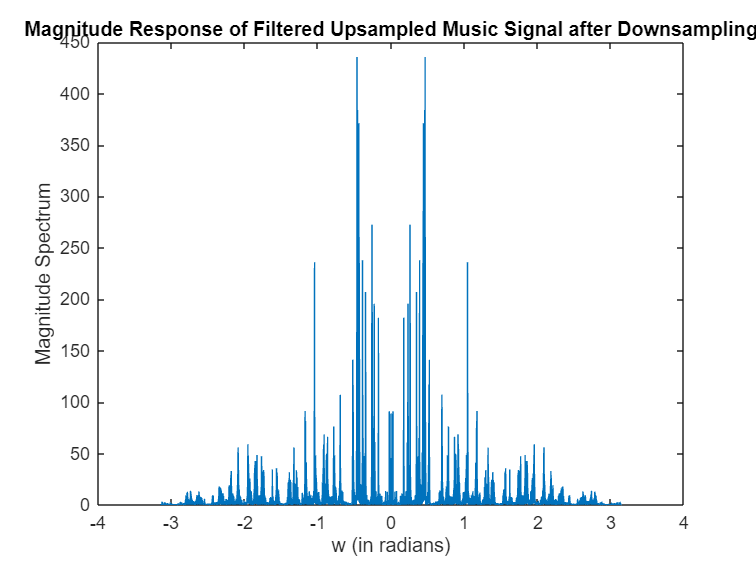

y_aa_ud2 = downsample(y_aa_u2,4);
Lud2 = Lu2/4;
Yaa_ud2 = fft(y_aa_ud2);
Yaa_ud2 = fftshift(Yaa_ud2);
w2ud = (-Lud2/2:Lud2/2-1) * (2*pi/Lud2);
plot(w2ud,abs(Yaa_ud2));
title('Magnitude Response of Filtered Upsampled Music Signal after Downsampling');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

sound(y_aa_ud2,3*Fs2/4);

### Observation

Here also there is no observable difference after comparing it with the original file. If we compare the magnitude plots of FFT of the two signals, we can see that there is very little aliasing. The reasoning being that we are upsampling first and then downsampling, there is little loss of information. 

## First filter each audio original signal with the LPF designed above, and downsample by 4. Then upsample by 3. Finally, interpolate each upsampled signal using an interpolation filter for L = 3 with support [−8,8] designed by any method (including windowing). (If you use ”intfilt” of Matlab, set α = 1.) Play these outputs and compare them with those of the previous part.

Filtering the speech signal.

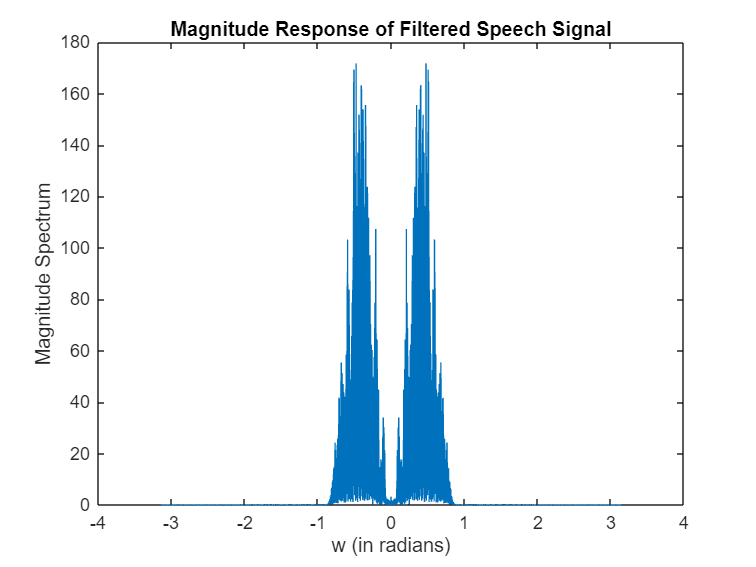

y_lp1 = filter(lpf3,y1);
Ylp1 = fft(y_lp1);
Ylp1 = fftshift(Ylp1);
plot(w1,abs(Ylp1));
title('Magnitude Response of Filtered Speech Signal');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

Downsampling the filtered signal by 4

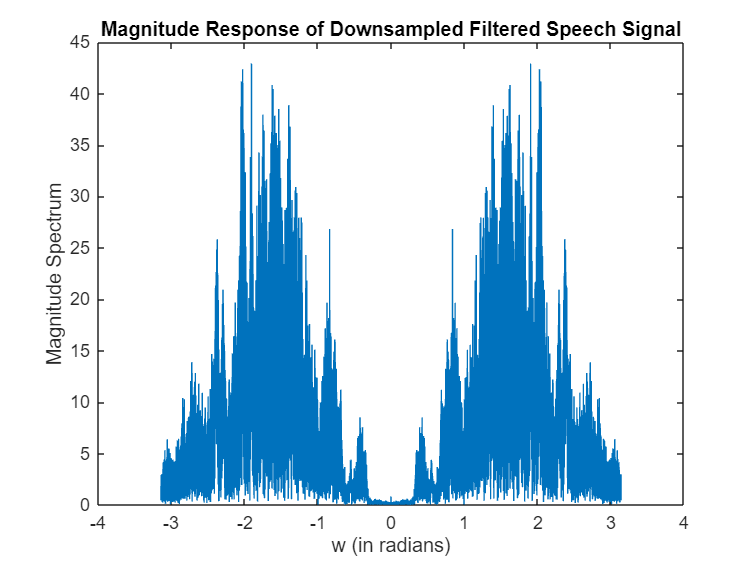

y_lp1_d = downsample(y_lp1,4);
L_d1 = L1/4;
Ylp_d1 = fft(y_lp1_d);
Ylp_d1 = fftshift(Ylp_d1);
w1d1 = (-L_d1/2:L_d1/2-1) * (2*pi/L_d1);
plot(w1d1,abs(Ylp_d1));
title('Magnitude Response of Downsampled Filtered Speech Signal');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

Upsampling the signal by 3.

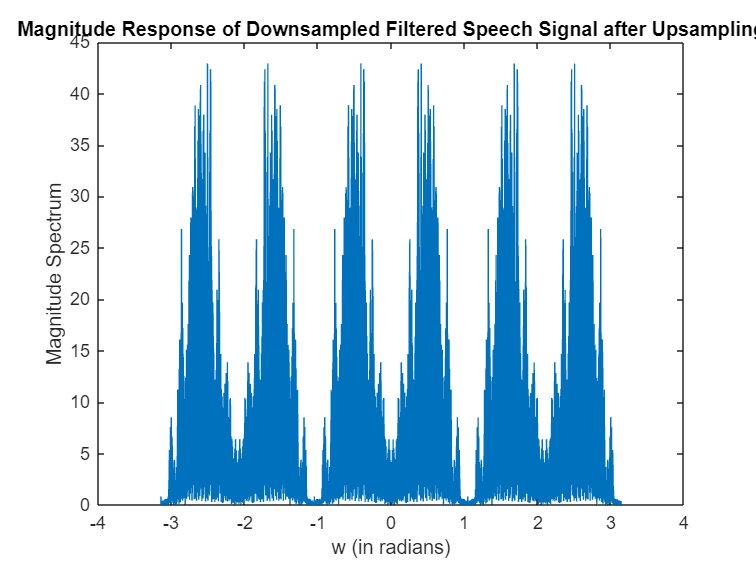

y_lp1_du = upsample(y_lp1_d,3);
Ldu1 = L_d1*3;
Ylp_du1 = fft(y_lp1_du);
Y1p_du1 = fftshift(Ylp_du1);
w1du = (-Ldu1/2:Ldu1/2-1) * (2*pi/Ldu1);
plot(w1du,abs(Ylp_du1));
title('Magnitude Response of Downsampled Filtered Speech Signal after Upsampling');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

Designing the interpolation filter

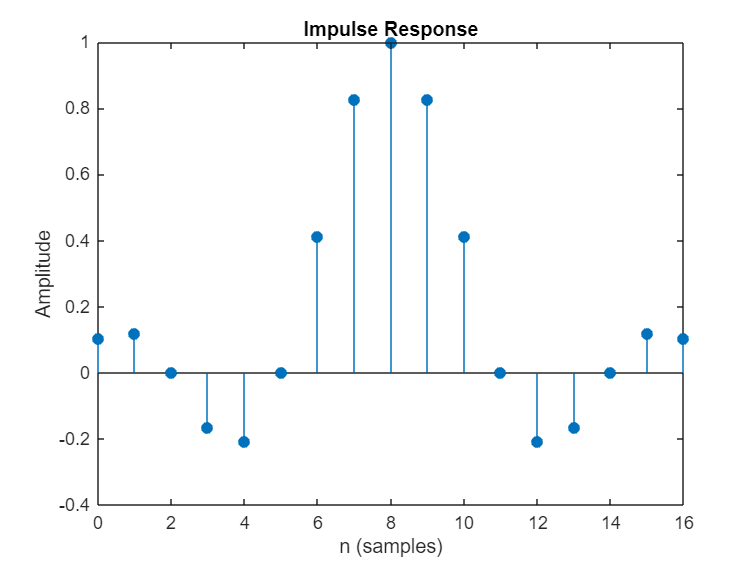

upfac = 3;
alpha = 1;
intp1 = intfilt(upfac,3,alpha);
fvtool(intp1);
impz(intp1);

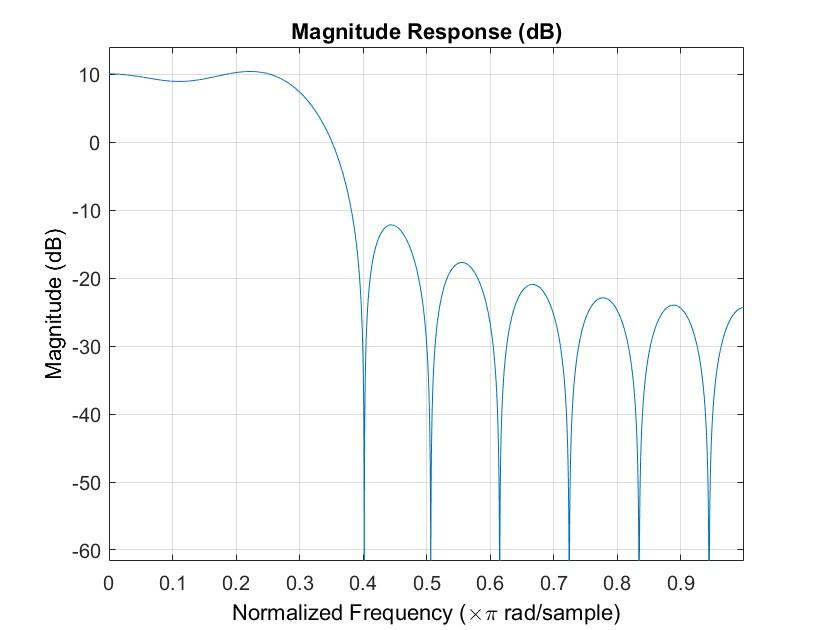

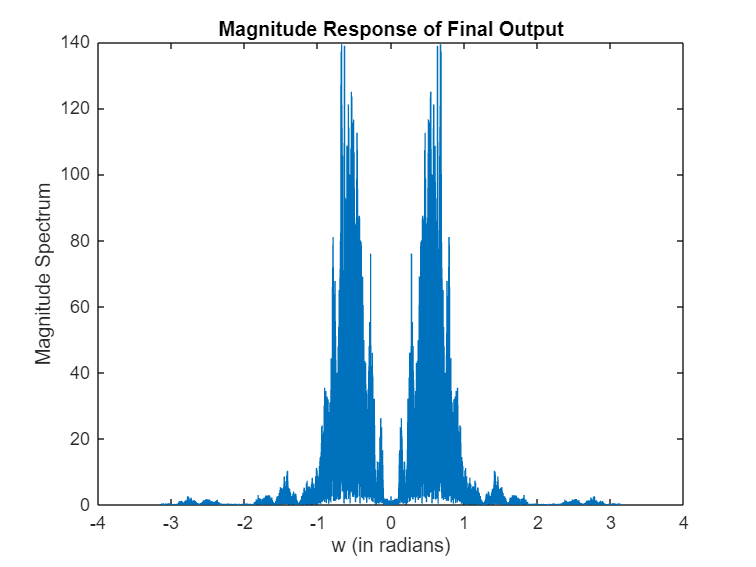

y_du1 = filter(intp1,1,y_lp1_du);
Ydu1 = fft(y_du1);
Ydu1 = fftshift(Ydu1);
plot(w1du,abs(Ydu1));
title('Magnitude Response of Final Output');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

sound(y_du1,3*Fs1/4);

### Observation

If we compare the outputs of problem 4 and problem 5, the signal we get after downsampling and then upsampling is less coherent. There also seems to be a loss of data after the operations, and it is harder to make out the words.

Filtering the music signal.

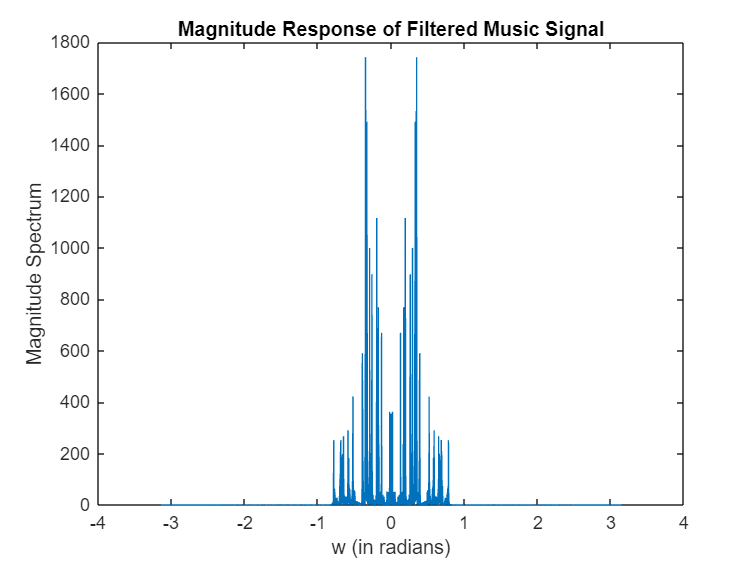

y_lp2 = filter(lpf4,y2);
Ylp2 = fft(y_lp2);
Ylp2 = fftshift(Ylp2);
plot(w2,abs(Ylp2));
title('Magnitude Response of Filtered Music Signal');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

Downsampling the filtered signal by 4.

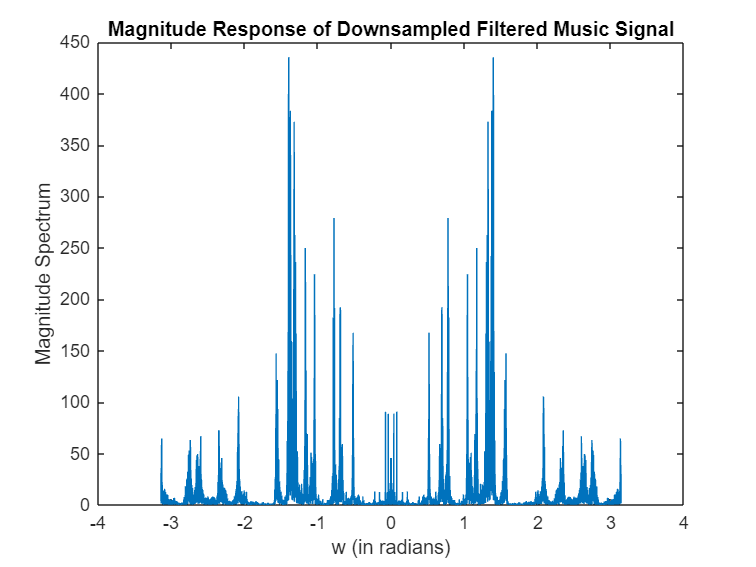

y_lp2_d = downsample(y_lp2,4);
L_d2 = L2/4;
Ylp_d2 = fft(y_lp2_d);
Ylp_d2 = fftshift(Ylp_d2);
w2d2 = (-L_d2/2:L_d2/2-1) * (2*pi/L_d2);
plot(w2d2,abs(Ylp_d2));
title('Magnitude Response of Downsampled Filtered Music Signal');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

Upsampling the signal by 3

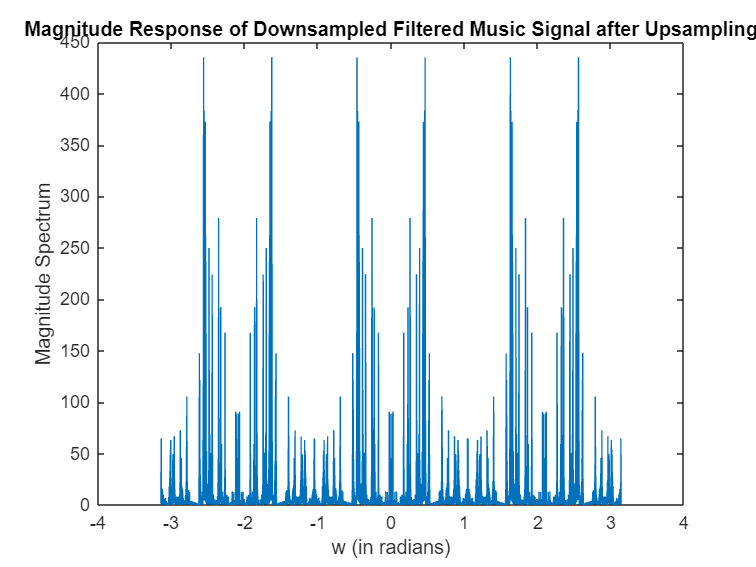

y_lp2_du = upsample(y_lp2_d,3);
Ldu2 = L_d2*3;
Ylp_du2 = fft(y_lp2_du);
Ylp_du2 = fftshift(Ylp_du2);
w2du = (-Ldu2/2:Ldu2/2-1) * (2*pi/Ldu2);
plot(w2du,abs(Ylp_du2));
title('Magnitude Response of Downsampled Filtered Music Signal after Upsampling');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

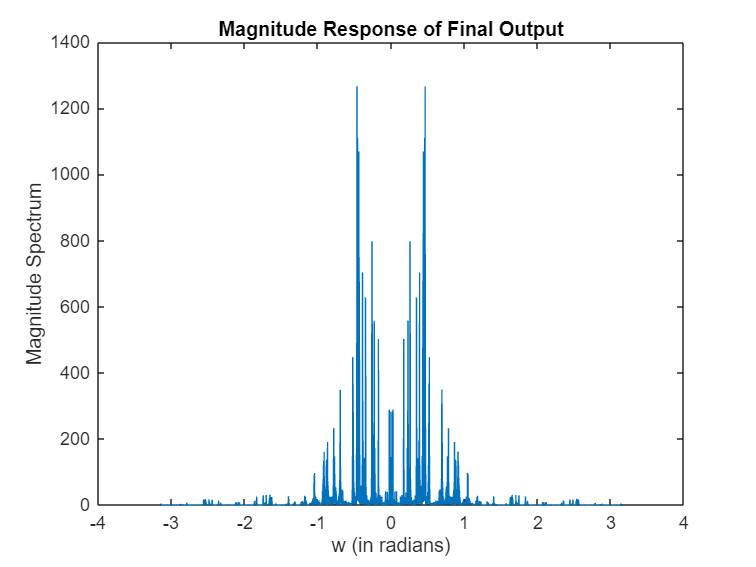

y_du2 = filter(intp1,1,y_lp2_du);
Ydu2 = fft(y_du2);
Ydu2 = fftshift(Ydu2);
plot(w2du,abs(Ydu2));
title('Magnitude Response of Final Output');
xlabel('w (in radians)');
ylabel('Magnitude Spectrum');

sound(y_du2,3*Fs2/4);

### Observation

We can observe that there is some difference between this and the original file. The audio is not clear, and there seems to be a loss of information. This is because we have used an Anti Aliasing filter at the start which removes some of the information from the original signal, which is obvious from the plots. 